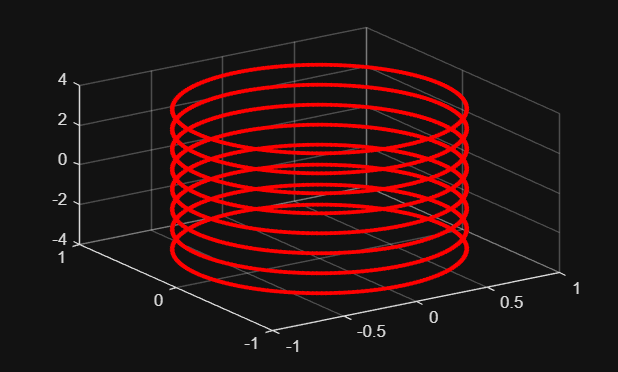

addpath('C:\Users\yared\Documents\MATLAB\Freno Magnético')

nl = 8; % número de espiras
N = 200; % Puntos en las espiras
R = 0.85; % Radio
R_circuito = 0.001;
sz = 1; % Distancia entre espiras
I = 1000; % Corriente
I_efectiva = I * N;
mo = 4*pi*1e-7; % Permeanilidad magnética
km = mo * I_efectiva / (4*pi); % Constante de Biot-Savart
rw = 0.2; % Constante de Biot-Savart
ds = 0.01; % Grosor entre los puntos de la malla
%ds = 0.05;
plot_option = true;

zo = 4.9;
dt = 0.01;

mag = 1035;
gamma = 0.08;
m = 50;
vz = 1;

r = 1e-5;
B_ring = 1;


[Px,Py,Pz,dx,dy,dz] = espiras(sz,nl,N,R);

%[Bz,z] = campoB(ds,km,Px,Py,Pz,dx,dy,nl,N,rw,plot_option);

plot_option = false

plot_option = logical
   0


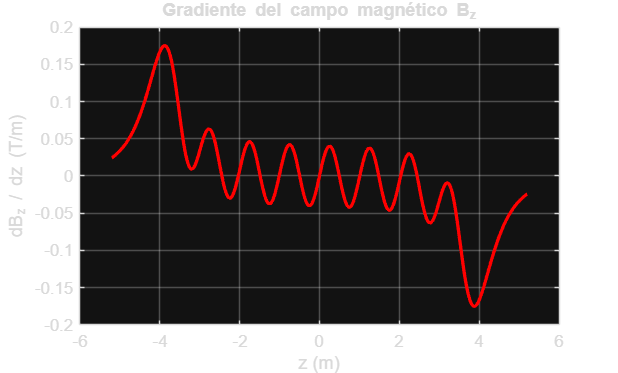


[Bz,z,dPhi_dz] = campoB(ds,km,Px,Py,Pz,dx,dy,nl,N,rw,plot_option,R);


disp(max(abs(dPhi_dz)))

    0.5654



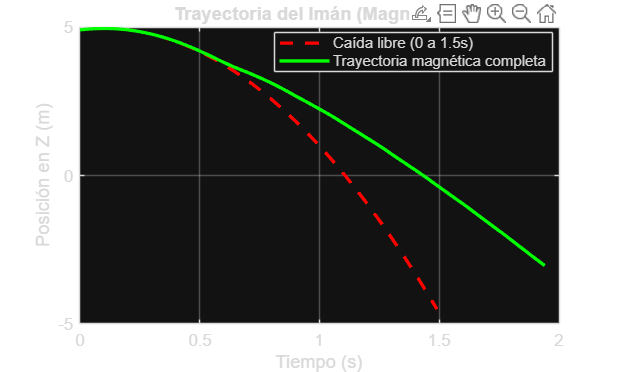

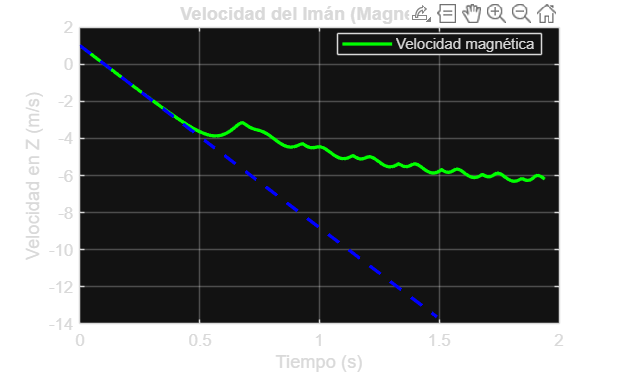

zm =     4.9000    4.9095    4.9180    4.9255    4.9321    4.9376    4.9422    4.9458    4.9484    4.9500    4.9506    4.9503    4.9490    4.9467    4.9434    4.9391    4.9339    4.9277    4.9205    4.9123    4.9032    4.8931    4.8820    4.8699    4.8569    4.8429    4.8280    4.8121    4.7952    4.7774    4.7586    4.7388    4.7182    4.6965    4.6739    4.6504    4.6260    4.6006    4.5743    4.5471    4.5190    4.4900    4.4602    4.4295    4.3979    4.3655    4.3323    4.2983    4.2636    4.2282



magnet = false;

zm = Trayectoria(Bz,z,mag,m,zo,dt,vz,gamma,magnet,dPhi_dz,R_circuito)